Cost function:

- maximize projectile kinetic energy at time of release

Constraints

- Rope tension always positive

- Spring displacement always positive 

- Specify feasible set

- Select a point in the feasible set

- Compute the model

- Compute the cost function

- Save parameters and cost result 

How do we specify feasible set?

- Simple range $x\in[a\ b]$

-     e.g. Arm length

- Constraints $x + y =c$

-     e.g. Spring params for const. energy

### Spring Energy and Force

Consider a spool of wire rigidly fixed to the arm and located coaxially with the pivot having a radius $l_3$. Attach one end of an extension spring to the wire and fix the other end of the spring to the structure. We'll call extending the spring a positive displacement. It will start with some initial positive displacement and move towards 0 after the trebuchet is released. We don't need to be concerned with the clocking of the spring mount at this time, so we'll remove the initial arm angle. The spring displacemnt $x_s$ may be modeled as


$$x_s = -l_3\left(\theta_1-\theta_{1_0}\right)+x_0$$


where $\theta_1$ is the arm position, $\theta_{1_0}$ is the starting arm position, $l_3$ is the radius of the winch drum, and $x_{s_0}$ is the starting spring displacement. The energy in the spring is given as


$$V_3=\frac12kx_s^2  $$


and the force it exerts is 


$$F_s=kx_s$$


What are the optimization variables, what are the costs, and what are the constraints?

The following are the optimization variables and inital guesses for the feasible ranges


$$l_3 \in [0.05\ 1.00]\text{ m}\\
\theta_{1_0} \in [0\ 360]\text{ degrees}\\
x_0 \in [0.05\ 1.00]\text{ m}\\
k \in [40\ 80000]\text{ N/m}$$


For now we won't factor any of these items into the cost. There are constraints to consider though. First, notice that if the displacement is strictly decreasing over time then the maximum energy and force are given by the initial displacement


$$V_{3_0}=\frac12kx_{s_0}^2,\quad F_{s_0}=kx_{s_0}$$


The first constraint is a feasibility constraint on $k$and $x_{s_0}$. We want to have a fixed amount of initial spring energy.


$$h_1({\bf x}) = \frac12kx_{s_0}^2-V_{3_0}=0$$


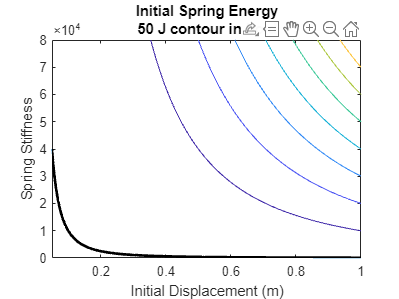

clear;
StartEnergy = 50;
kFeasible = [40 80000];
xFeasible = [0.05 1.00];
fEnergy = @(x,k) (1/2)*k.*x.^2;
fStartingContour = @(x,k) (fEnergy(x,k) - StartEnergy);
fcontour(fEnergy,[xFeasible kFeasible]);
hold on;
fimplicit(fStartingContour,[xFeasible kFeasible],'k','LineWidth',2);
xlabel("Initial Displacement (m)");
ylabel("Spring Stiffness");
title({"Initial Spring Energy",sprintf("%.f J contour in bold",StartEnergy)});

We can probably combine these two optimization variables into one and remove the constraint equation if we create a new variable that paramaterizes the relationship.

I was going to put a constraint on the range of motion of the spring, but actually I think we can make the device free-wheel when the spring travel is reached. Instead, I'll modify the force and energy functions to reflect the freewheeling using the Heaviside step function $H$


$$V_3=\frac12k\left(x_sH(x_s)\right)^2,\quad F_s=kx_sH(x_s)$$


This change reflects the wire on the spring going slack when spring is released rather than turning the spring into a compression spring.

We need to clean up the code so the initial values can be speciefied better.

- Need way to define feasible space

- Need cost function that takes optimization vector as input

We want feasible regions for all elements in `sysparam`. The concept of a feasible region only applies to the optimiziation routine and shouldn't be part of the kinematic model.

save("Optimization\FeasibleRegion","FeasibleRegion");
disp(FeasibleRegion)

            Comment             stuct_name       field_name       MinFeasible    MaxFeasible    Default    IncludeInOptimization
    ________________________    ___________    _______________    ___________    ___________    _______    _____________________

    "Arm Position"              "init_cond"    "theta_1_0"            -360              0        -135              true         
    "Arm Vel"                   "init_cond"    "theta_dot_1_0"           0              0           0              false        
    "Rope  Position"            "init_cond"    "theta_2_0"            -360              0        -135              true         
    "Rope Vel"                  "init_cond"    "theta_dot_2_0"           0              0           0              f

We want $f({\bf x})$ cost function:

clear all;
clc;

tic;
SymbolicParameters;

Lagrangian Symvars:


$$\left(\begin{array}{ccccccccccccc} g & k & l_{1} & l_{2} & l_{3} & m_{1} & m_{2} & \theta_{1} & \theta_{1,0} & \theta_{2} & {\dot{\theta }}_{1} & {\dot{\theta }}_{2} & x_{3,0} \end{array}\right)$$

DefineSystemParameters;
DeriveEquationsOfMotion;
SolveDifferentialEquationsOfMotion;

Columns should match:


$$\left(\begin{array}{cc} \theta_{2} & \theta_{2}\\ {\mathrm{Dtheta}}_{2} & {\mathrm{Dtheta}}_{2}\\ \theta_{1} & \theta_{1}\\ {\mathrm{Dtheta}}_{1} & {\mathrm{Dtheta}}_{1} \end{array}\right)$$

Lagrangian f_of_t Symvars:


$$t$$

LoadSolution;

E:\Projects\Trebuchet\GitHub\Trebuchet\Model\solutions\20251026-2132-DiffEqnSolution.mat
Lagrangian Symvars:


$$\left(\begin{array}{ccccccccccccc} g & k & l_{1} & l_{2} & l_{3} & m_{1} & m_{2} & \theta_{1} & \theta_{1,0} & \theta_{2} & {\dot{\theta }}_{1} & {\dot{\theta }}_{2} & x_{3,0} \end{array}\right)$$

Lagrangian f_of_t Symvars:


$$t$$

Quick Stats:
  0.85 = t_release : time of release
  8.41 = T_2_release : Proj. Kinetic Energy at release


DispSysVar(sysparam.discrete.T_2_release);

$$\left(T_{2,\mathrm{rel}}=T_{2}\left(t_{\mathrm{rel}}\right)\right)=8.4$$

cost = -double(sysparam.discrete.T_2_release.subsexpr);
fprintf("Cost: %f\n",cost);

Cost: -8.409787


toc

Elapsed time is 9.297772 seconds.



% Save results to table including all parameters and resulting cost